# Transmitter Simulation

Applying QPSK modulation on the transmitting bits

## Clear variables

clc;
clear all;
close all;


## Initialiazing Input Variables

N_data = 100;    % length of information bits
A = 1;          % Amplitude of the symbols



## Simulation Method - 1

Tx_constellation = A*[exp(j*pi/4), exp(j*3*pi/4), exp(j*5*pi/4), exp(j*7*pi/4)];    % generating QPSK constellation

Tx_bits = round(rand(1,N_data));    % Random data generation

Tx_bits =      0     0     1     0     1     0     1     0     1     1     1     1     0     1     0     0     1     1     0     1     1     1     1     1     1     0     0     1     0     0     0     1     1     1     0     0     1     0     0     1     0     1     1     1     0     1     1     1     1     1



group_of_2_bits = reshape(Tx_bits,2,N_data/2);  % grouping the data sequence to 2 bits. As QPSK can transmit 2 bits at a time

group_of_2_bits =      0     1     1     1     1     1     0     0     1     0     1     1     1     0     0     0     1     0     1     0     0     1     0     1     1     0     1     0     0     1     0     0     1     0     1     0     0     0     1     1     0     1     1     1     1     1     0     0     1     1
     0     0     0     0     1     1     1     0     1     1     1     1     0     1     0     1     1     0     0     1     1     1     1     1     1     0     0     0     1     0     1     1     0     0     0     0     0     1     0     0     1     0     0     1     1     0     1     0     1     0



Tx_bits_mapping_1to4 = group_of_2_bits(1,:)*2+group_of_2_bits(2,:)+1;   % converying data to have values only from 1 to 4, to be able to be mapped according to QPSK constellation

Tx_bits_mapping_1to4 =      1     3     3     3     4     4     2     1     4     2     4     4     3     2     1     2     4     1     3     2     2     4     2     4     4     1     3     1     2     3     2     2     3     1     3     1     1     2     3     3     2     3     3     4     4     3     2     1     4     3



Tx_symbols = Tx_constellation(Tx_bits_mapping_1to4) % Final QPSK symbols according to the input data

Tx_symbols =    0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i


## Plots

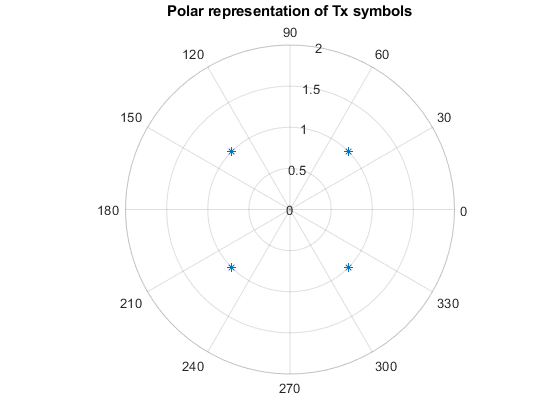

figure
polarplot(angle(Tx_symbols),abs(Tx_symbols),'*')
title('Polar representation of Tx symbols');

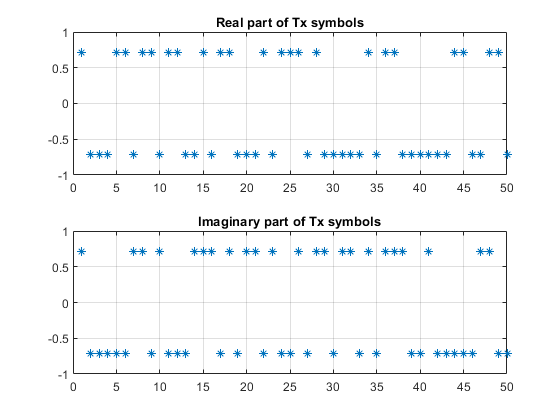


figure
subplot(2,1,1)
plot(real(Tx_symbols),'*')
grid
title('Real part of Tx symbols')
subplot(2,1,2)
plot(imag(Tx_symbols),'*')
grid
title('Imaginary part of Tx symbols')